# Filter

% Set Simulation Time
end_time = 5;
delta_t = 0.001;
sim_time = [0:0.001:5]; 
% Set Sine Wave
sine_mag = 2;
sine_freq = 1;

#### Sine Simulation

n =1;
for(t=0:delta_t:end_time)
    y = sine_mag * sin(sine_freq*(2*pi*t));
    % get data
    sim_y(n) = y;
    n = n + 1;
end

#### Set Minimum and Maximum Parameters

% Time Domain
Xmin = 0.0; 
XTick = 1.0;
Xmax = end_time;
Ymin = -5.0;
YTick = 1.0;
Ymax = 5.0;

#### Generate Sine Wave with Noise

sine_mag1 = 2.0; sine_freq1 = 1.0;          % 크기 2, 주파수 1
sine_mag2 = 0.5; sine_freq2 = 10.0;         % 크기 0.5 주파수 10
for(t=0:delta_t:end_time)
    y_noise1 = sine_mag1*sin(sine_freq1*(2*pi*sim_time));
    y_noise2 = sine_mag1*sin(sine_freq1*(2*pi*sim_time))...
        + sine_mag2*sin(sine_freq2*(2*pi*sim_time));
    y_noise3 = sine_mag1*sin(sine_freq1*(2*pi*sim_time))...
        + sine_mag2*sin(sine_freq2*(2*pi*sim_time))...
        + 0.8*randn(size(sim_time));        % 평균 0 표준편차 0.8
end

## **Movig Average Filter**

N = 1;
win_size = 100;                             % Sampling size
for(t=0:delta_t:end_time)
    %simulation
    MAF_Sum = 0;                            % Temporary variable that having sum
    MAF_Cnt = 0;                            % Temporary variable that having count
    for(i=N-floor(win_size/2)+1 : N+ceil(win_size/2))
                                            % floor : 버림 함수
                                            % ceil  : 올림 함수
                                            % N 양옆으로 win_size만큼 Sampling을 취함
        try
            MAF_Sum = MAF_Sum + y_noise3(i);
                                            % Sampling
            MAF_Cnt = MAF_Cnt + 1;
                                            % Count
        catch
            continue
        end
    end
    sim_MAF_Y(N) = sum(MAF_Sum)/MAF_Cnt;    % (Sampling Sum)/(Sampling num)
    N = N +1;                               % N++
end

## Low Pass Filter

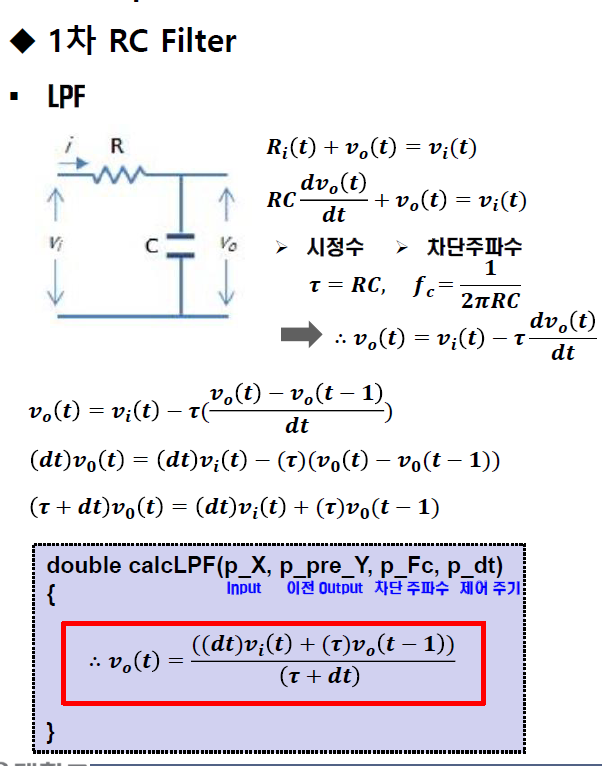

%LPF
cutoff_f = 2;                                  % Cutoff Frequency

tau = 1/(2*pi*cutoff_f);                         % tau = 시정수
pre_LPF_Y = 0;                                  % 이전 결과값을 저장하는 변수

m = 1;

for(t=delta_t:delta_t:end_time)
    LPF_Y = (((delta_t)*y_noise3(m)+(tau)*pre_LPF_Y)/(tau + delta_t));
    pre_LPF_Y = LPF_Y;
    
    % get Data
    sim_LPF_Y(m+1) = LPF_Y;
    m = m+1;
end

#### Set and Calculate Fast Fourier Transform

% Set FFT
Fs       = 1/delta_t;       % Sampling Frequency
T        = delta_t;         % Sampling Period
L_none        = length(y_noise3);   % Lengh of Signal
L_MAF        = length(sim_MAF_Y);   % Lengh of Signal
L_LPF        = length(sim_LPF_Y);   % Lengh of Signal
T_vector = (0:L-1)*T;       % Time Vector

Non Filter FFT

% Calc FFT
fft_f_none    = Fs*(0:(L_none/2))/L_none;  % Frequency Range 분석 주파수 분해능
fft_y_temp_none     = abs(fft(y_noise3)/L_none);     % 허수부 제거
fft_y_none          = fft_y_temp_none(1:L_none/2+1);   % 켤레 복소수 대응 1

fft_y_none(2:end-1) = 2*fft_y_none(2:end-1);      % 켤레 복소수 대응 2

MAF FFT

% Calc FFT
fft_f_MAF    = Fs*(0:(L_MAF/2))/L_MAF;  % Frequency Range 분석 주파수 분해능
fft_y_temp_MAF     = abs(fft(sim_MAF_Y)/L_MAF);     % 허수부 제거
fft_y_MAF          = fft_y_temp_MAF(1:L_MAF/2+1);   % 켤레 복소수 대응 1

fft_y_MAF(2:end-1) = 2*fft_y_MAF(2:end-1);      % 켤레 복소수 대응 2

LPF FFT

% Calc FFT
fft_f_LPF    = Fs*(0:(L_LPF/2))/L_LPF;  % Frequency Range 분석 주파수 분해능
fft_y_temp_LPF     = abs(fft(sim_LPF_Y)/L_LPF);     % 허수부 제거
fft_y_LPF          = fft_y_temp_LPF(1:L_LPF/2+1);   % 켤레 복소수 대응 1

fft_y_LPF(2:end-1) = 2*fft_y_LPF(2:end-1);      % 켤레 복소수 대응 2

## Draw Graph

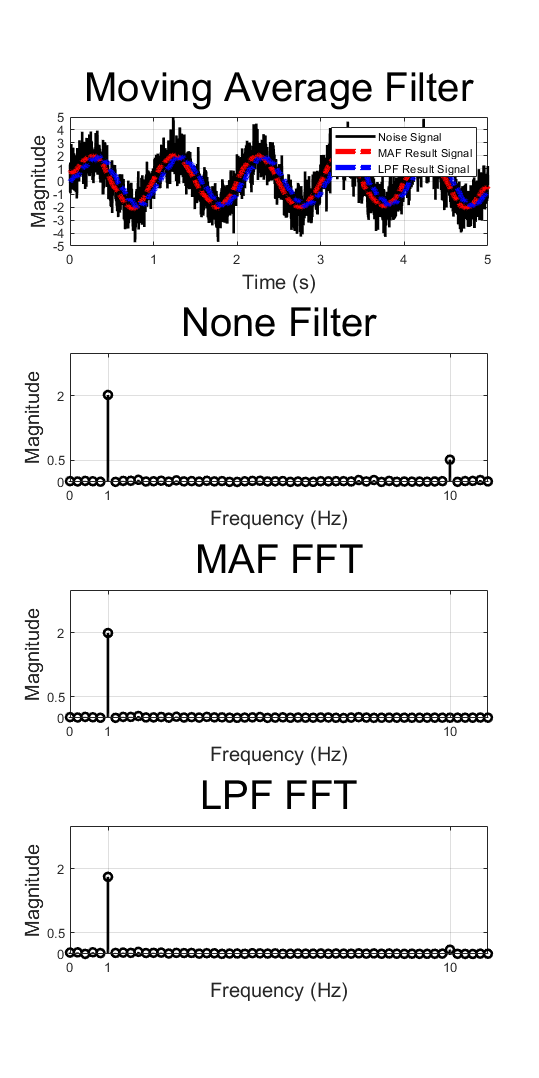

figure('units','pixels','pos',[500 1000 1000 2000],'Color',[1 1 1]);
    subplot(4,1,1);                             % Noise Sine Wave Plot
        
        plot(sim_time,y_noise3,'-k','LineWidth',2);
        hold on;                                % Drawing Graphs
        plot(sim_time,sim_MAF_Y,'-.r','LineWidth',4);
                                                % MAF Result Wave
        hold on;
        plot(sim_time,sim_LPF_Y,'-.b','LineWidth',4)
                                                % LPF Result Wave
        legend('Noise Signal','MAF Result Signal','LPF Result Signal');
                                                % Set Legend
                                                
        grid on;                                % Grid On
        axis([Xmin Xmax Ymin Ymax]);            % Graph 최대 최소 설정
        set(gca, 'XTick', [Xmin:XTick:Xmax]);   % X축 Grid 간격
        set(gca, 'YTick', [Ymin:YTick:Ymax]);   % Y축 Grid 간격
        
        xlabel('Time (s)',    "FontSize",15); 
        ylabel('Magnitude',    "FontSize",15);
        title('Moving Average Filter',    "FontSize",30);
    
    subplot(4,1,2);                             % None Filter FFT
        Xxmin = 0.0; Xxmax = 11;
        Yymin = 0.0; Yymax = 3.0;
    
        stem(fft_f_none,fft_y_none,'-k','LineWidth',2);
        
        grid on;                            % Grid On
        axis([Xxmin Xxmax Yymin Yymax]);    % Graph 최대 최소 설정
        set(gca,'XTick',[0 1.0 10.0]);      % X축 Grid 간격
        set(gca,'YTick',[0 0.5 2.0]);       % Y축 Grid 간격

        xlabel('Frequency (Hz)',    "FontSize",15);
        ylabel('Magnitude',    "FontSize",15);
        title('None Filter',    "FontSize",30);
        
    subplot(4,1,3);                             % MAF FFT
    
        stem(fft_f_MAF,fft_y_MAF,'-k','LineWidth',2);
        
        grid on;                            % Grid On
        axis([Xxmin Xxmax Yymin Yymax]);    % Graph 최대 최소 설정
        set(gca,'XTick',[0 1.0 10.0]);      % X축 Grid 간격
        set(gca,'YTick',[0 0.5 2.0]);       % Y축 Grid 간격

        xlabel('Frequency (Hz)',    "FontSize",15);
        ylabel('Magnitude',    "FontSize",15);
        title('MAF FFT',    "FontSize",30);
        
    subplot(4,1,4);                             % LPF FFT
    
        stem(fft_f_LPF,fft_y_LPF,'-k','LineWidth',2);
        
        grid on;                            % Grid On
        axis([Xxmin Xxmax Yymin Yymax]);    % Graph 최대 최소 설정
        set(gca,'XTick',[0 1.0 10.0]);      % X축 Grid 간격
        set(gca,'YTick',[0 0.5 2.0]);       % Y축 Grid 간격

        xlabel('Frequency (Hz)',    "FontSize",15);
        ylabel('Magnitude',    "FontSize",15);
        title('LPF FFT',    "FontSize",30);    